# Modelo del caso de estudio de clase

bloque funciones

%Deficición de la función de manera simbolica
syms Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j)

%Definición de la transformación homógenea general
Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j) = [cos(ai_j)*cos(bi_j) cos(ai_j)*sin(bi_j)*sin(gi_j)-sin(ai_j)*cos(gi_j) sin(ai_j)*sin(gi_j)+cos(ai_j)*sin(bi_j)*cos(gi_j) x_i_j; sin(ai_j)*cos(bi_j) cos(ai_j)*cos(gi_j)+sin(ai_j)*sin(bi_j)*sin(gi_j) sin(ai_j)*sin(bi_j)*cos(gi_j)-cos(ai_j)*sin(gi_j) y_i_j; -sin(bi_j) cos(bi_j)*sin(gi_j) cos(bi_j)*cos(gi_j) z_i_j; 0 0 0 1]

$$Tij(x\_i\_j, y\_i\_j, z\_i\_j, gi\_j, bi\_j, ai\_j) = \left(\begin{array}{cccc} \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)-\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)+\cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right) & x_{i,j}\\ \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)+\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)-\cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & y_{i,j}\\ -\sin\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right) & z_{i,j}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Posición de Home

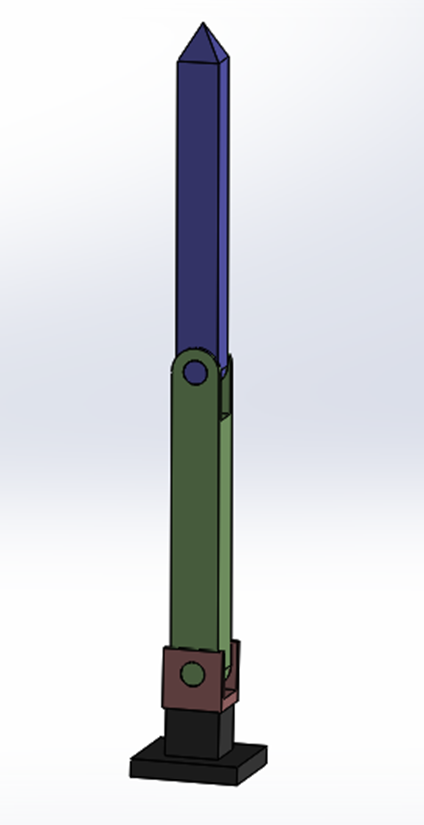

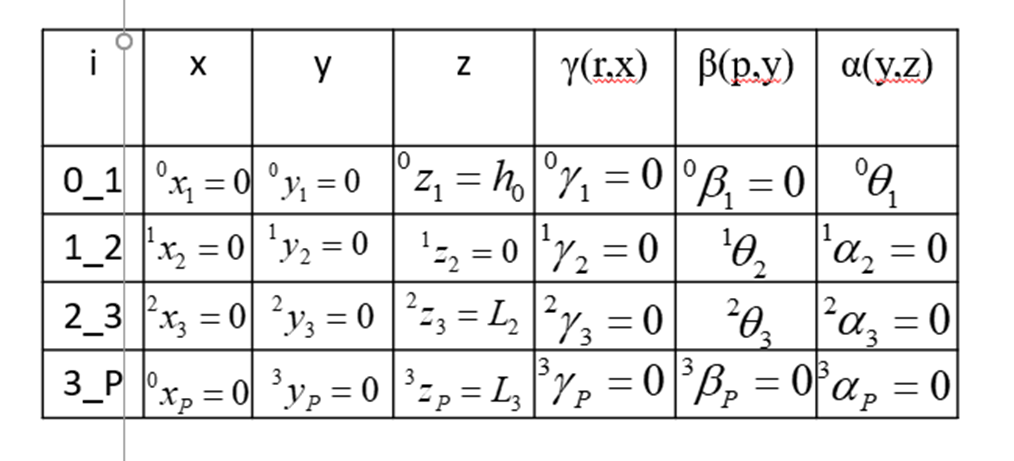

## Cálculo de las transformaciones 

Transformación entre {0} y el sistema de referencia {1}

syms T_0_1 h_0 theta_0_1 theta_1_2 L_2 L_3 theta_2_3

T_0_1 = Tij(0,0,h_0,0,0,theta_0_1)

$$T\_0\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & 0 & 0\\ \sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & 0 & 0\\ 0 & 0 & 1 & h_{0}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_1_2 = Tij(0,0,0,0,theta_1_2,0)

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{1,2}\right) & 0 & \sin\left(\theta_{1,2}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{1,2}\right) & 0 & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_2_3 = Tij(0,0,L_2,0,theta_2_3,0)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{2,3}\right) & 0 & \sin\left(\theta_{2,3}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{2,3}\right) & 0 & \cos\left(\theta_{2,3}\right) & L_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_3_P = Tij(0,0,L_3,0,0,0)

$$T\_3\_P = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & L_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_0_P = simplify(T_0_1*T_1_2*T_2_3*T_3_P)

$$T\_0\_P = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\cos\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & \sin\left(\theta_{1,2}+\theta_{2,3}\right)\,\cos\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right)\,\sigma_{1}\\ \cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & \sin\left(\theta_{1,2}+\theta_{2,3}\right)\,\sin\left(\theta_{0,1}\right) & \sin\left(\theta_{0,1}\right)\,\sigma_{1}\\ -\sin\left(\theta_{1,2}+\theta_{2,3}\right) & 0 & \cos\left(\theta_{1,2}+\theta_{2,3}\right) & h_{0}+L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+L_{2}\,\cos\left(\theta_{1,2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+L_{2}\,\sin\left(\theta_{1,2}\right) \end{array}$$

syms xi_0_P p_0_P theta_0_P

p_0_P = [T_0_P(1,4);T_0_P(2,4);T_0_P(3,4)]

$$p\_0\_P = \left(\begin{array}{c} \cos\left(\theta_{0,1}\right)\,\left(L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+L_{2}\,\sin\left(\theta_{1,2}\right)\right)\\ \sin\left(\theta_{0,1}\right)\,\left(L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+L_{2}\,\sin\left(\theta_{1,2}\right)\right)\\ h_{0}+L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+L_{2}\,\cos\left(\theta_{1,2}\right) \end{array}\right)$$


theta_0_P = [T_0_P(1,1);T_0_P(2,2);T_0_P(3,3)]

$$theta\_0\_P = \left(\begin{array}{c} \cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\cos\left(\theta_{0,1}\right)\\ \cos\left(\theta_{0,1}\right)\\ \cos\left(\theta_{1,2}+\theta_{2,3}\right) \end{array}\right)$$


xi_0_P = [p_0_P;theta_0_P]

$$xi\_0\_P = \left(\begin{array}{c} \cos\left(\theta_{0,1}\right)\,\left(L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+L_{2}\,\sin\left(\theta_{1,2}\right)\right)\\ \sin\left(\theta_{0,1}\right)\,\left(L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+L_{2}\,\sin\left(\theta_{1,2}\right)\right)\\ h_{0}+L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+L_{2}\,\cos\left(\theta_{1,2}\right)\\ \cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\cos\left(\theta_{0,1}\right)\\ \cos\left(\theta_{0,1}\right)\\ \cos\left(\theta_{1,2}+\theta_{2,3}\right) \end{array}\right)$$

### Modelo cinemático directo

Cálculo de la matriz Jacobiana con los elementos de la posición

syms J_theta w

J_theta = simplify(jacobian(p_0_P,[theta_0_1,theta_1_2, theta_2_3]))

$$J\_theta = \begin{array}{l} \left(\begin{array}{ccc} -\sin\left(\theta_{0,1}\right)\,\sigma_{2} & \cos\left(\theta_{0,1}\right)\,\sigma_{1} & L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\cos\left(\theta_{0,1}\right)\\ \cos\left(\theta_{0,1}\right)\,\sigma_{2} & \sin\left(\theta_{0,1}\right)\,\sigma_{1} & L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)\,\sin\left(\theta_{0,1}\right)\\ 0 & -\sigma_{3}-L_{2}\,\sin\left(\theta_{1,2}\right) & -\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+L_{2}\,\cos\left(\theta_{1,2}\right)\\ \sigma_{2}=\sigma_{3}+L_{2}\,\sin\left(\theta_{1,2}\right)\\ \sigma_{3}=L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right) \end{array}$$

%cálculo de la manipulabiulidad

w = simplify(det(J_theta))

$$w = L_{2}\,L_{3}\,\left(-L_{3}\,\cos\left(\theta_{1,2}\right)\,{\cos\left(\theta_{2,3}\right)}^{2}+L_{3}\,\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{2,3}\right)\,\cos\left(\theta_{2,3}\right)+L_{3}\,\cos\left(\theta_{1,2}\right)+L_{2}\,\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{2,3}\right)\right)$$